# Solving ZDT1

## Constraints & Solver

N = 3; % Variables in x vector
Functions = {@f1, @f2}; % Objective functions
M = length(Functions);
Maximum = 1;

RefPoints = 100;
f1_vals = zeros(1, RefPoints);
f2_vals = zeros(1, RefPoints);

wvals = linspace(1e-5, Maximum-1e-5, RefPoints);
zvals = linspace(1e-5, Maximum-1e-5, RefPoints);

rng(128);

for i = 1:RefPoints
    z = rand(1, M);  % Initial decision vector
    w = [0.5 0.5]; 
    w = w / norm(w); % Normalize `w'
    
    assert (length(z) == M);
    assert (length(w) == M);
    
    % Non-Linear Conditions for ASF
    C1 = @(x) ASFCondition(x(1:N), Functions{1}, z(1), w(1));
    C2 = @(x) ASFCondition(x(1:N), Functions{2}, z(2), w(2));
    
    % Final Objective function
    Objective = @(x) ASF(x, Functions, M, z, w);
    
    % Bounds
    L = zeros(1, N+1);  
    U =  ones(1, N+1) * Maximum;
    
    x0 = rand(1, N+1) * Maximum;

    fprintf("Iter [%2d] Solving ...\n", i);
    options = optimoptions('fmincon', 'Algorithm', 'sqp', 'TolFun', 1e-9, 'TolX', 1e-9, 'MaxFunctionEvaluations', 1e5, 'Display', 'None');
    [x, fval, exitflag, output] = fmincon(Objective, x0, [], [], [], [], L, U, @(x)Constraint(x, C1, C2), options);
    f1_vals(i) = f1(x(1:end-1));
    f2_vals(i) = f2(x(1:end-1));
    
    
end

Iter [ 1] Solving ...


    0.7421         0         0    0.7199


Iter [ 2] Solving ...


    0.5880         0         0    0.4999


Iter [ 3] Solving ...


    0.8046    0.0000    0.2187    0.0661


Iter [ 4] Solving ...


    0.5284         0         0    0.8610


Iter [ 5] Solving ...


    0.6223         0         0    0.7155


Iter [ 6] Solving ...


    0.5108         0    0.4433    0.4643


Iter [ 7] Solving ...


    0.3702         0         0    0.8140


Iter [ 8] Solving ...


    0.7159    0.0000    0.2666    0.1401


Iter [ 9] Solving ...


    0.4192         0         0    0.0510


Iter [10] Solving ...


    0.4792         0         0    0.0325


Iter [11] Solving ...


    0.3916         0         0    0.9417


Iter [12] Solving ...


    0.4615         0         0    0.3243


Iter [13] Solving ...


    0.0521         0         0    0.1265


Iter [14] Solving ...


    0.0184         0         0    0.7958


Iter [15] Solving ...


    0.0166         0         0    0.6524


Iter [16] Solving ...


    0.3657         0         0    0.1568


Iter [17] Solving ...


    0.8648         0         0    0.0099


Iter [18] Solving ...


    0.4296         0         0    0.7906


Iter [19] Solving ...


    0.8535         0    0.0577    0.6035


Iter [20] Solving ...


    0.3462         0         0    0.0688


Iter [21] Solving ...


    0.7519         0         0    0.5433


Iter [22] Solving ...


    0.3337         0         0    0.3261


Iter [23] Solving ...


    0.1241         0         0    0.8939


Iter [24] Solving ...


    0.3527         0         0    0.2703


Iter [25] Solving ...


    0.1867         0         0    0.1429


Iter [26] Solving ...


    0.8346    0.0000    0.4116    0.5060


Iter [27] Solving ...


    0.2827         0         0    0.6469


Iter [28] Solving ...


    0.1445         0         0    0.9151


Iter [29] Solving ...


    0.9094         0         0    0.8140


Iter [30] Solving ...


    0.2960         0         0    0.3106


Iter [31] Solving ...


    0.4305         0         0    0.7969


Iter [32] Solving ...


    0.5784         0         0    0.5618


Iter [33] Solving ...


    0.4101         0         0    0.5896


Iter [34] Solving ...


    0.2862         0         0    0.1021


Iter [35] Solving ...


    0.3117         0         0    0.4726


Iter [36] Solving ...


    0.3926         0         0    0.0929


Iter [37] Solving ...


    0.4287         0         0    0.6260


Iter [38] Solving ...


    0.4396    0.0000    0.1504    0.0980


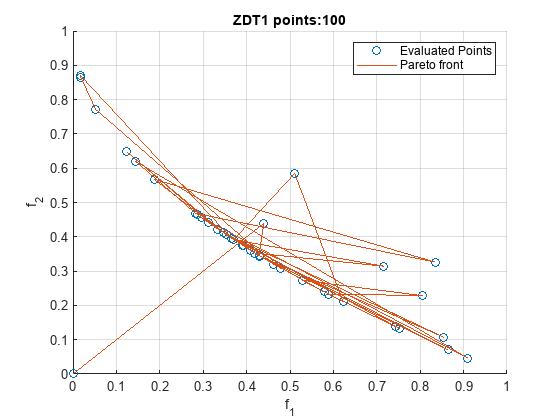

figure;
hold on;
scatter(f1_vals, f2_vals);
plot(f1_vals, f2_vals);
hold off;
xlim([0 1]);
xlabel("f_1")
ylim([0 1]);
ylabel("f_2");
grid on;
title(strcat("ZDT1 points:", num2str(RefPoints)))
legend('Evaluated Points', 'Pareto front')

## Functions

function ret = f1(x)
    ret = x(1);
end

function ret = f2(x)
    G = 1 + sum(x(2:end));
    ret = G * (1 - sqrt(x(1) ./ G));
end

function ret = ASFCondition(x, Fn, z, w)
    ret = (Fn(x) - z) ./ w - x(end);
end

function [c, ceq] = Constraint(x, C1, C2)
    c = [C1(x); C2(x)];
    ceq = [];
end

% Handles alpha
function ret = ASF(x, Functions, M, z, w)
    C = zeros([1 M]);

    x = x(1:end-1);  % alpha is not required
    for i = 1:M
        C(i) = (Functions{i}(x) - z(i)) ./ w(i);
    end
    ret = max(C);
end